# File Selector

This widget provides a file path edit field along with a button that opens a file selection dialog. 

Create a figure with a grid layout:

figObj = uifigure("Position",[100 100 400 150]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);
gridObj.RowHeight = 30;

Create and configure the widget:

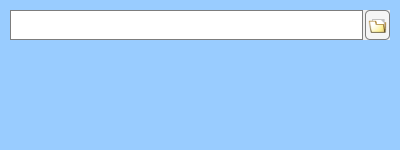

fileWidget = wt.FileSelector(gridObj);

fileWidget.ValueChangedFcn = @(src,evt)disp(evt)

fileWidget =   FileSelector with properties:

     ValueChangedFcn: @(src,evt)disp(evt)

               Value: ""
              Filter: [0×0 string]
            FullPath: ""
    ValueIsValidPath: 0
       SelectionType: file
       RootDirectory: ""
         ShowHistory: off
             History: [0×1 string]
    DefaultDirectory: ""
             Tooltip: ""
          FieldColor: [1 1 1]
         ButtonColor: [0.9600 0.9600 0.9600]

            Position: [11 111 380 30]
               Units: 'pixels'

  Show all properties


Set the value programmatically:

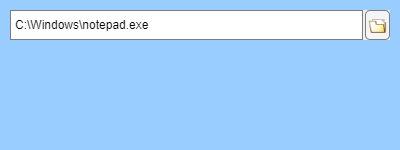

fileWidget.Value = "C:\Windows\notepad.exe";

You may configure the field as an editable dropdown to enable selecting items from recent history:

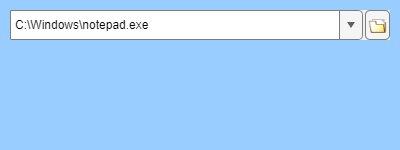

fileWidget.ShowHistory = true;

If the path does not resolve to a valid file, you will see a warning icon:

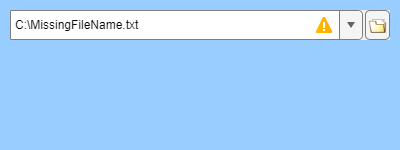

fileWidget.Value = "C:\MissingFileName.txt";

You can configure it for specifying an output file that may not yet exist. In this configuration, the button will utilize the `uiputfile` dialog:

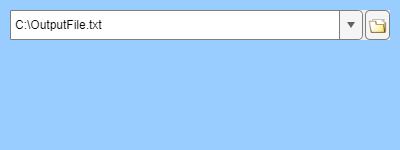

fileWidget.SelectionType = "putfile";
fileWidget.Value = "C:\OutputFile.txt";

You may change mode to select a folder instead. In this configuration, the button will utilize the `uigetdir` dialog:

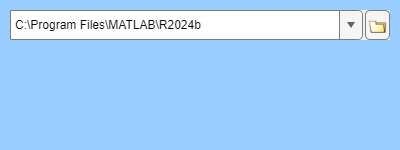

fileWidget.SelectionType = "folder";
fileWidget.Value = matlabroot;

*Copyright 2020-2025 The MathWorks, Inc.*